# **WITHIN SUBJECT ANALYSIS**

For example, are there group differences in power, for nodes with low amounts of centrality, or high amounts of centrality, or both?

## First retreive Master Data Set

cog_task_list = {'PVT'};
df_long =  dflong('cogtestlist',cog_task_list,'getd2cdf',false);


Getting GPSD during PVT Task. . . . . . . . . . . . -done

Getting Network Props during PVT: . . . . . . . . . . . . -done


clearvars -except df_long

# CHOOSE YOUR SETTINGS

cogtask = 'PVT';
bandname  = 'delta';
ntwprop_X = 'deg_w'; 
ntwprop_X_level  = sprintf('%s_level',ntwprop_X);
ntwprop_Y = 'gpsd'; 
catvars = 3;
t=1;
testtype = 'ranksum';
printSummResults = 'off';
printAllResults = 'off';
suppresswarn = true;


## INIT STUFF

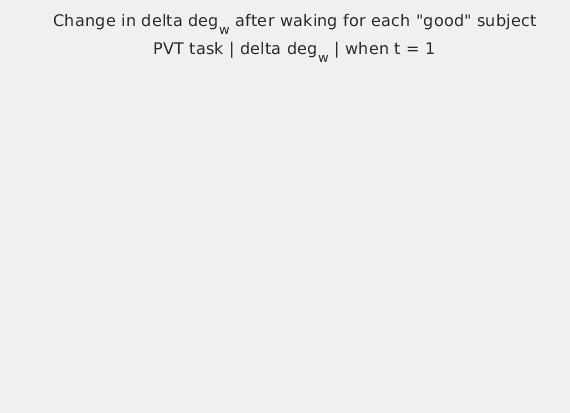

desired_vars = [{ntwprop_Y},{ntwprop_X},{ntwprop_X_level},experimentalvars()];

settings_str = sprintf('%s task | %s %s | when t = %d',cogtask, bandname, ntwprop_X, t);
anzinfo_str = sprintf('Change in %s %s after waking for each "good" subject',bandname, ntwprop_X);
title_str = sprintf('%s\n%s',anzinfo_str, settings_str);

sbjid_set = goodsbj(cogtask);
S = subjects(cogtask);
sbjset_chan_dCtrlVsBl = zeros(23,1);
sbjset_chan_dLightVsBl = zeros(23,1);


%% INIT FIGURE
close all force
figure('Visible','on');
T = tiledlayout(ceil(numel(sbjid_set)/2),6);
T.Title.String = title_str;

drawnow;


# ANALYSIS/PLOTS OF INDIVIDUAL SUBJECT DATA

for i = 1:numel(sbjid_set)
    sbj_id = sbjid_set(i);

    % GET THE NETWORK PROP VALUES
    df_long_sbj = df_long(df_long.sbj == sbj_id,:);
    df     = dflong2wide(df_long_sbj, cogtask, {'baseline', 'control','light'}, bandname, t, 'grouping_vars',[],'keepchannels',true,'catvars',catvars,'suppresswarnings',suppresswarn);
    [df_bl, df_ctrl, df_light] = splitdfbycondition(df);
    
    % GET CHANEL VALUES
    sbj_chan_dCtrlVsBl =   (df_ctrl.(ntwprop_X)) - (df_bl.(ntwprop_X));
    sbj_chan_dLightVsBl =   (df_light.(ntwprop_X)) - (df_bl.(ntwprop_X));
    
    sbjset_chan_dCtrlVsBl = sbjset_chan_dCtrlVsBl + sbj_chan_dCtrlVsBl;
    sbjset_chan_dLightVsBl = sbjset_chan_dLightVsBl + sbj_chan_dLightVsBl;
    

    % TOPOPLOT CONTROL
    sbj_clr = rand(1,3);

    % SCATTER PLOTS LIGHT
    ax_scatter = nexttile;
    boxchart(ax_scatter, df.condition,df.(ntwprop_Y),'GroupByColor',df.(ntwprop_X_level));
    title_str  = sprintf('Sbj %d', sbj_id);
    title(title_str,'Color',sbj_clr,'FontSize',8);     
    set(ax_scatter,'Color',sbj_clr);

    drawnow


end

Error using dflong2wide
Invalid argument name 'catvars'. Name must be 'grouping_vars', 'keepchannels', or 'suppresswarnings'.

# ANALYSIS WITH AGGREGATED DATA

clearvars -except df_long

cogtask = 'PVT';
bandname  = 'delta';
ntwprop_X = 'deg_w'; 
ntwprop_Y = 'gpsd'; 
numlevels = 3;
t=1;


ntwprop_Y_mean =  sprintf('mean_%s',ntwprop_Y);
ntwprop_X_level  = sprintf('%s_level',ntwprop_X);
desired_vars = [{ntwprop_Y},{ntwprop_X},experimentalvars()];


df     = dflong2wide(df_long, cogtask, {'baseline', 'control','light'}, bandname, t,'keepchannels',true);
df = df(:,desired_vars);


[df_bl, df_ctrl, df_light] = splitdfbycondition(df);
df_bl_sbj_set = splitdfbysubject(df_bl);

numsbj = numel(df_bl_sbj_set)


df_bl_cat = cellfun(@(df) [df catnetworkprop(df,ntwprop_X,numlevels)],df_bl_sbj_set,'UniformOutput',false);
df_bl_cat = cat(1,df_bl_cat{:});


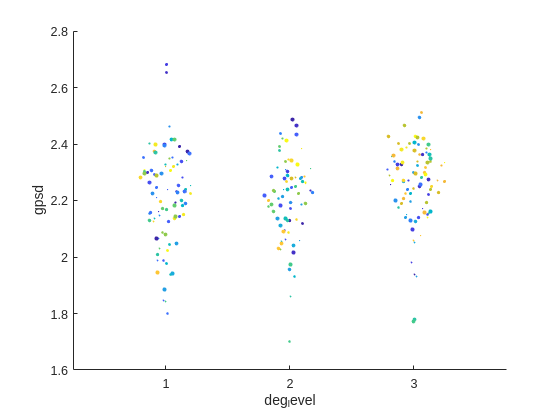

close all force;
figure
nexttile;
hold on

df_bl.sbj = categorical(df_bl.sbj);

scatter(df_bl,ntwprop_X_level,ntwprop_Y,"filled",'ColorVariable',"chan",'SizeData',df_bl.sbj,'XJitter','density','XJitterWidth',.5,'YJitter','rand','YJitterWidth',.1)


% SCATTER PLOTS
ax_scatter = nexttile;
boxchart(ax_scatter, df.condition,df.(ntwprop_Y),'GroupByColor',df.(ntwprop_X_level));
title_str  = 'Aggregated data';
title(title_str,'Color','k','FontSize',8);     
set(ax_scatter,'Color','k');


drawnow